# **Check camera connection for Tello drone**

接続テスト

以下のサポートパッケージのイントールが必用です

- MATLAB Support Package for Ryze Tello Drones

参照Webページを開いておきましょう

- [https://jp.mathworks.com/help/supportpkg/ryzeio/](https://jp.mathworks.com/help/supportpkg/ryzeio/)

- [https://jp.mathworks.com/help/supportpkg/ryzeio/ug/connect-to-ryze-drone-over-wifi.html](https://jp.mathworks.com/help/supportpkg/ryzeio/ug/connect-to-ryze-drone-over-wifi.html)

- [https://jp.mathworks.com/help/supportpkg/ryzeio/ug/troubleshoot-video-stream-access.html](https://jp.mathworks.com/help/supportpkg/ryzeio/ug/troubleshoot-video-stream-access.html)

接続のためのWifiアドレス確認

- バッテリーを外した部分にWIFI：TELLO-EDCXXXと記載したシールが張ってあるので番号をメモします

- スマホのアプリTelloで接続して、パスワードを設定し、再起動後見られるWifiで接続し、Telloアプリで画像が見られることを確認します

Wifiで接続し、以下を実行します

ryzeObj = ryze()
cameraObj = camera(ryzeObj)
preview(cameraObj)

エラーが出たら、上記のWebページを参考に再度試してみてください。

エラーが発生せず画像を取得できたらテスト成功です！

引き続き、以下を実行して終了します

clear cameraObj
clear ryzeObj 

# **Take chessboard image for camera calibration**

clear cameraObj
clear ryzeObj 
numImages=3;
count=1;

%Create destination folder
startingFolder = pwd;
destinationFolder = [startingFolder,'\caliberate']

destinationFolder = 'C:\UTokyo\course\sem2\3799-023 創造性工学プロジェクトII\caliberate'

if ~exist(destinationFolder, 'dir')
  mkdir(destinationFolder);
end
dinfo = dir(destinationFolder);
dinfo([dinfo.isdir]) = []; 
filenames = fullfile(destinationFolder, {dinfo.name});
if ~isempty(filenames)
    delete( filenames{:} )
end
% PC付属のウェブカメラを使う場合はtrue, Telloの実機を使う場合は falseにする
useWebcam = false;
if useWebcam
    ryzeObj = [];
    cameraObj = webcam;
    img = snapshot(cameraObj);
else
    ryzeObj = ryze()
    cameraObj = camera(ryzeObj);
    img = snapshot(cameraObj);
    if ryzeObj.State ~= "landed"
        land(ryzeObj);
    end
end
preview(cameraObj)
while ~isempty(img) && count<=numImages
    img = snapshot(cameraObj);
    w = waitforbuttonpress;
    if w==1 
        close all;
        outputBaseName = ['calibrationimage',num2str(count), '.JPG']
        fullDestinationFileName = fullfile(destinationFolder, outputBaseName);
        imshow(img);
        imwrite(img, fullDestinationFileName);
        count=count+1;
    end
end
closePreview(cameraObj)  


# **Choose image for camera calibration**

files = cell(1, numImages);
for i = 1:numImages
    files{i} = fullfile(destinationFolder,sprintf('opencv_frame_%d.png', i))
end

files = 1×3 cell array
    {'C:\UTokyo\course\sem2\3799-023 創造性工学プロジェクトII\caliberate\opencv_frame_1.png'}    {0×0 double}    {0×0 double}


files = 1×3 cell array
    {'C:\UTokyo\course\sem2\3799-023 創造性工学プロジェクトII\caliberate\opencv_frame_1.png'}    {'C:\UTokyo\course\sem2\3799-023 創造性工学プロジェクトII\caliberate\opencv_frame_2.png'}    {0×0 double}


files = 1×3 cell array
    {'C:\UTokyo\course\sem2\3799-023 創造性工学プロジェクトII\caliberate\opencv_frame_1.png'}    {'C:\UTokyo\course\sem2\3799-023 創造性工学プロジェクトII\caliberate\opencv_frame_2.png'}    {'C:\UTokyo\course\sem2\3799-023 創造性工学プロジェクトII\caliberate\opencv_frame_3.png'}


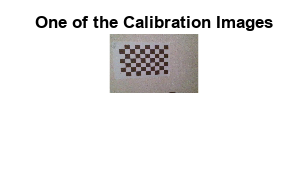


% Display one of the calibration images
magnification = 25;
I = imread(files{1});
figure; imshow(I, InitialMagnification = magnification);
title("One of the Calibration Images");

# **Estimate camera parameters**

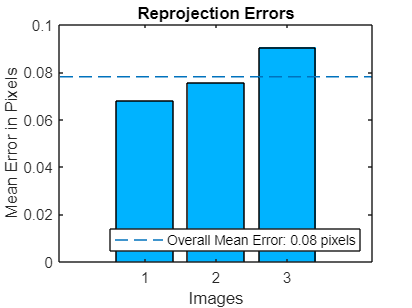

% Detect the checkerboard corners in the images.
[imagePoints, boardSize] = detectCheckerboardPoints(files);

% Generate the world coordinates of the checkerboard corners in the
% pattern-centric coordinate system, with the upper-left corner at (0,0).
squareSize = 20; % in millimeters
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Calibrate the camera.
imageSize = [size(I, 1), size(I, 2)];
cameraParams = estimateCameraParameters(imagePoints, worldPoints, ...
                                     ImageSize = imageSize);

% Evaluate calibration accuracy.
figure; showReprojectionErrors(cameraParams);
title("Reprojection Errors");

# **Read the Image of Objects to Be Measured**

Load the image containing objects to be measured. This image includes the calibration pattern, and the pattern is in the same plane as the objects you want to measure. In this example, both the pattern and the coins are on the same table top.

Alternatively, you could use two separate images: one containing the pattern, and the other containing the objects to be measured. Again, the objects and the pattern must be in the same plane. Furthermore, images must be captured from exactly the same view point, meaning that the camera must be fixed in place.

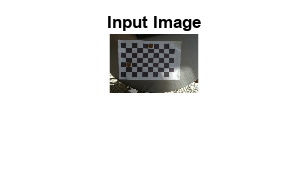

imOrig = imread(fullfile(startingFolder, "opencv_frame_0.png"));
figure; imshow(imOrig, InitialMagnification = magnification);
title("Input Image");

# **Undistort the Image**

Use the cameraParameters object to remove lens distortion from the image. This is necessary for accurate measurement.

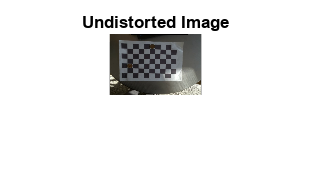

% Since the lens introduced little distortion, use 'full' output view to illustrate that
% the image was undistored. If we used the default 'same' option, it would be difficult
% to notice any difference when compared to the original image. Notice the small black borders.
[im, newOrigin] = undistortImage(imOrig, cameraParams, OutputView = "full");
figure; imshow(im, InitialMagnification = magnification);
title("Undistorted Image");

# **Segment Coins**

In this case, the coins are colorful on white background. Use the saturation component of the HSV representation of the image to segment them out.

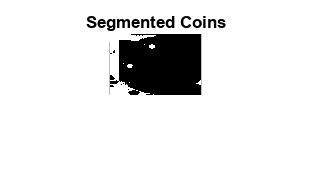

% Convert the image to the HSV color space.
imHSV = rgb2hsv(im);

% Get the saturation channel.
saturation = imHSV(:, :, 2);

% Threshold the image
t = graythresh(saturation);
imCoin = (saturation > t);

figure; imshow(imCoin, InitialMagnification = magnification);
title("Segmented Coins");

# **Detect Coins**

We can assume that the two largest connected components in the segmented image correspond to the coins.

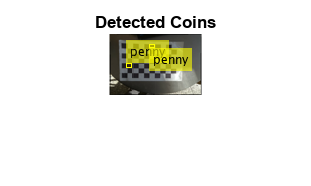

% Find connected components.
blobAnalysis = vision.BlobAnalysis(AreaOutputPort = true,...
    CentroidOutputPort = false,...
    BoundingBoxOutputPort = true,...
    MinimumBlobArea = 200, ExcludeBorderBlobs = true);
[areas, boxes] = step(blobAnalysis, imCoin);

% Sort connected components in descending order by area
[~, idx] = sort(areas, "Descend");

% Get the two largest components.
boxes = double(boxes(idx(1:2), :));

% Reduce the size of the image for display.
scale = magnification / 100;
imDetectedCoins = imresize(im, scale);

% Insert labels for the coins.
imDetectedCoins = insertObjectAnnotation(imDetectedCoins, "rectangle", ...
    scale * boxes, "penny");
figure; imshow(imDetectedCoins);
title("Detected Coins");

# **Compute Extrinsics**

To map points in the image coordinates to points in the world coordinates we need to compute the rotation and the translation of the camera relative to the calibration pattern. Note that the `estimateExtrinsics` function assumes that there is no lens distortion. In this case imagePoints have been detected in an image that has already been undistorted using [`undistortImage`](https://www.mathworks.com/help/vision/ref/undistortimage.html).

% Detect the checkerboard.
[imagePoints, boardSize] = detectCheckerboardPoints(im);

% Adjust the imagePoints so that they are expressed in the coordinate system
% used in the original image, before it was undistorted.  This adjustment
% makes it compatible with the cameraParameters object computed for the original image.
imagePoints = imagePoints + newOrigin; % adds newOrigin to every row of imagePoints

% Extract camera intrinsics.
camIntrinsics = cameraParams.Intrinsics;

% Compute extrinsic parameters of the camera.
camExtrinsics = estimateExtrinsics(imagePoints, worldPoints, camIntrinsics);

# **Measure the First Coin**

To measure the first coin we convert the top-left and the top-right corners of the bounding box into world coordinates. Then we compute the Euclidean distance between them in millimeters.

% Adjust upper left corners of bounding boxes for coordinate system shift 
% caused by undistortImage with output view of 'full'. This would not be
% needed if the output was 'same'. The adjustment makes the points compatible
% with the cameraParameters of the original image.
boxes = boxes + [newOrigin, 0, 0]; % zero padding is added for width and height

% Get the top-left and the top-right corners.
box1 = double(boxes(1, :));
imagePoints1 = [box1(1:2); ...
                box1(1) + box1(3), box1(2)];

% Get the world coordinates of the corners            
worldPoints1 = img2world2d(imagePoints1, camExtrinsics, camIntrinsics);

% Compute the diameter of the coin in millimeters.
d = worldPoints1(2, :) - worldPoints1(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf("Measured diameter of one penny = %0.2f mm\n", diameterInMillimeters);

Measured diameter of one penny = 21.50 mm


# **Measure the Second Coin**

Measure the second coin the same way as the first coin.

% Get the top-left and the top-right corners.
box2 = double(boxes(2, :));
imagePoints2 = [box2(1:2); ...
                box2(1) + box2(3), box2(2)];

% Apply the inverse transformation from image to world            
worldPoints2 = img2world2d(imagePoints2, camExtrinsics, camIntrinsics);

% Compute the diameter of the coin in millimeters.
d = worldPoints2(2, :) - worldPoints2(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf("Measured diameter of the other penny = %0.2f mm\n", diameterInMillimeters);

Measured diameter of the other penny = 20.13 mm


# **Measure the Distance to The First Coin**

In addition to measuring the size of the coin, we can also measure how far away it is from the camera.

% Compute the center of the first coin in the image.
center1_image = box1(1:2) + box1(3:4)/2;

% Convert to world coordinates.
center1_world  = img2world2d(center1_image, camExtrinsics, camIntrinsics);

% Remember to add the 0 z-coordinate.
center1_world = [center1_world 0];

% Compute the distance to the camera.
cameraPose = extr2pose(camExtrinsics);
cameraLocation = cameraPose.Translation;
distanceToCamera = norm(center1_world - cameraLocation);
fprintf("Distance from the camera to the first penny = %0.2f mm\n", ...
    distanceToCamera);

Distance from the camera to the first penny = 351.21 mm


# **References**

[1] Z. Zhang. A flexible new technique for camera calibration. IEEE Transactions on Pattern Analysis and Machine Intelligence, 22(11):1330-1334, 2000.

# Change param and calculate again

cameraParams2 = toStruct(cameraParams)

cameraParams2 = struct with fields:
                   RadialDistortion: [-0.0067 -0.0792]
               TangentialDistortion: [0 0]
                          ImageSize: [240 360]
                        WorldPoints: [54×2 double]
                         WorldUnits: 'mm'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0
                    RotationVectors: [3×3 double]
                 TranslationVectors: [3×3 double]
                 ReprojectionErrors: [54×2×3 double]
                                  K: [3×3 double]
                  DetectedKeypoints: [54×3 logical]
                            Version: []


cameraParams2 = cameraParameters(cameraParams2)

cameraParams2 =   cameraParameters with properties:

   Camera Intrinsics
                         Intrinsics: [1×1 cameraIntrinsics]

   Camera Extrinsics
                  PatternExtrinsics: [3×1 rigidtform3d]

   Accuracy of Estimation
              MeanReprojectionError: 0.0781
                 ReprojectionErrors: [54×2×3 double]
                  ReprojectedPoints: [54×2×3 double]

   Calibration Settings
                        NumPatterns: 3
                  DetectedKeypoints: [54×3 logical]
                        WorldPoints: [54×2 double]
                         WorldUnits: 'mm'
                       EstimateSkew: 0
    NumRadialDistortionCoefficients: 2
       EstimateTangentialDistortion: 0


imOrig = imread(fullfile(startingFolder, "opencv_frame_0.png"));
figure; imshow(imOrig, InitialMagnification = magnification);
title("Input Image");

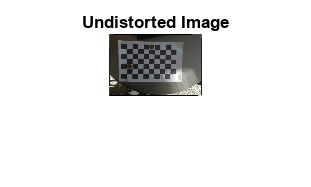


% Since the lens introduced little distortion, use 'full' output view to illustrate that
% the image was undistored. If we used the default 'same' option, it would be difficult
% to notice any difference when compared to the original image. Notice the small black borders.
[im, newOrigin] = undistortImage(imOrig, cameraParams2, OutputView = "full");
figure; imshow(im, InitialMagnification = magnification);
title("Undistorted Image");

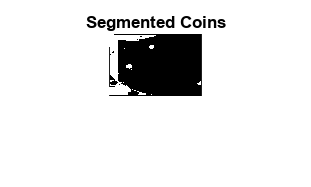


% Convert the image to the HSV color space.
imHSV = rgb2hsv(im);

% Get the saturation channel.
saturation = imHSV(:, :, 2);

% Threshold the image
t = graythresh(saturation);
imCoin = (saturation > t);

figure; imshow(imCoin, InitialMagnification = magnification);
title("Segmented Coins");

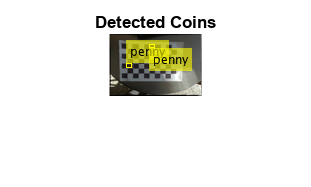


% Find connected components.
blobAnalysis = vision.BlobAnalysis(AreaOutputPort = true,...
    CentroidOutputPort = false,...
    BoundingBoxOutputPort = true,...
    MinimumBlobArea = 200, ExcludeBorderBlobs = true);
[areas, boxes] = step(blobAnalysis, imCoin);

% Sort connected components in descending order by area
[~, idx] = sort(areas, "Descend");

% Get the two largest components.
boxes = double(boxes(idx(1:2), :));

% Reduce the size of the image for display.
scale = magnification / 100;
imDetectedCoins = imresize(im, scale);

% Insert labels for the coins.
imDetectedCoins = insertObjectAnnotation(imDetectedCoins, "rectangle", ...
    scale * boxes, "penny");
figure; imshow(imDetectedCoins);
title("Detected Coins");


% Detect the checkerboard.
[imagePoints, boardSize] = detectCheckerboardPoints(im);

% Adjust the imagePoints so that they are expressed in the coordinate system
% used in the original image, before it was undistorted.  This adjustment
% makes it compatible with the cameraParameters object computed for the original image.
imagePoints = imagePoints + newOrigin; % adds newOrigin to every row of imagePoints

% Extract camera intrinsics.
camIntrinsics2 = cameraParams2.Intrinsics;

% Compute extrinsic parameters of the camera.
camExtrinsics2 = estimateExtrinsics(imagePoints, worldPoints, camIntrinsics2);

% Adjust upper left corners of bounding boxes for coordinate system shift 
% caused by undistortImage with output view of 'full'. This would not be
% needed if the output was 'same'. The adjustment makes the points compatible
% with the cameraParameters of the original image.
boxes = boxes + [newOrigin, 0, 0]; % zero padding is added for width and height

% Get the top-left and the top-right corners.
box1 = double(boxes(1, :));
imagePoints1 = [box1(1:2); ...
                box1(1) + box1(3), box1(2)];

% Get the world coordinates of the corners            
worldPoints1 = img2world2d(imagePoints1, camExtrinsics2, camIntrinsics2);

% Compute the diameter of the coin in millimeters.
d = worldPoints1(2, :) - worldPoints1(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf("Measured diameter of one penny = %0.2f mm\n", diameterInMillimeters);

Measured diameter of one penny = 21.60 mm



% Get the top-left and the top-right corners.
box2 = double(boxes(2, :));
imagePoints2 = [box2(1:2); ...
                box2(1) + box2(3), box2(2)];

% Apply the inverse transformation from image to world            
worldPoints2 = img2world2d(imagePoints2, camExtrinsics2, camIntrinsics2);

% Compute the diameter of the coin in millimeters.
d = worldPoints2(2, :) - worldPoints2(1, :);
diameterInMillimeters = hypot(d(1), d(2));
fprintf("Measured diameter of the other penny = %0.2f mm\n", diameterInMillimeters);

Measured diameter of the other penny = 20.13 mm



% Compute the center of the first coin in the image.
center1_image = box1(1:2) + box1(3:4)/2;

% Convert to world coordinates.
center1_world  = img2world2d(center1_image, camExtrinsics2, camIntrinsics2);

% Remember to add the 0 z-coordinate.
center1_world = [center1_world 0];

% Compute the distance to the camera.
cameraPose = extr2pose(camExtrinsics);
cameraLocation = cameraPose.Translation;
distanceToCamera = norm(center1_world - cameraLocation);
fprintf("Distance from the camera to the first penny = %0.2f mm\n", ...
    distanceToCamera);

Distance from the camera to the first penny = 351.24 mm
